# Informe Laboratorio: Análisis Numérico

# Práctica No. 7

**Juan Pablo Jiménez Gómez **

**Código: 2173051**

**Grupo: B2**

*Escuela de ingeniería de sistemas e informática*

*Universidad Industrial de Santander*

12 de Febrero del 2021

## **Introduction:**

For the next laboratory we will practice the adjustment of curves for different exercises, in addition to this, we will be asked to make a program that can find the line of least squares for which the line y = Ax + B of a family can be calculated of points presented in the respective statements, having defined values for vectors X and Y with their respective positions. After this, we will be asked to create graphs to test if the line passes through the points or near them, and in addition to this, determine the error of a function from which its points have been previously calculated and the line is calculated with its values of A and B.

#### **3 Practice**

#### ** 3.1 Understanding **

#### **Answer with your own words the following questions:**

- (0.2 points) What is curve fitting?

Curve fitting is a process widely used in numerical methods which consists of constructing a curve which refers to the mathematical function that is being worked on, said curve is subject to a series of restrictions and is adjusted to a series of points. which are given data to work the exercise in a certain way. The adjustment of curves in many cases implies the use of interpolation when it is necessary to work with the data, and in the same way, the case of constructing a function that can be named as a smooth function arises, which can be adjusted in an approximate way to the data worked in the exercise.

- (0.2 points) How to calculate the least-squares line?

It is necessary to calculate the values of the slope m and b which will be the intercept of y in the equation of the line


$$y=\textrm{mx}+b$$


where y = the height of the line, x = the length of the line, m = the slope, that is, how steep the line is, b = the y-intercept

To find the line of best fit to calculate the N points, the following steps must be followed:

To calculate each point (x, y) we must calculate $x^2$  and xy

all x, y, $x^2$, xy must be added which gives us the respective summations for: $\Sigma x,\Sigma y,\Sigma x^2 ,\Sigma \textrm{xy},$

calculate the slope m using the following formula:


$$m=\frac{N*\Sigma \left(\textrm{xy}\right)-\Sigma x*\Sigma y}{N\Sigma \left(x^2 \right)-{\left(\Sigma x\right)}^2 }$$


When N is the number of points. Now we calculate the intercept of b


$$b=\frac{\Sigma y-m\Sigma x}{N}$$


We construct the equation of the line


$$y=\textrm{mx}+b$$


- (0.2 points) What is data linearization?

Suppose that we are given the points ($x_1$; $y_1$); ($x_2$; $y_2$); ......; ($x_N$; $y_N$) and want to fit an exponential curve of the form:

 
$$y={\textrm{Ce}}^{\textrm{AX}}$$


The first step is to take the logarithm of both sides:

 
$$\ln \left(y\right)=\textrm{Ax}\ln \left(C\right)$$


Then introduce the change of variables:

   
$$Y=\;\ln \left(y\right)\;;X=x;\;B\;=\ln \left(C\right)$$


This results in a linear relation between the new variables X and Y:

 
$$Y=\textrm{AX}+B$$


The original points ($x_k ,y_k$) in the xy-plane are transformed into the points ($X_k ,Y_k$) = ($x_k$, $\ln \left(y_k \right)$) in the XY-plane. This process is called data linearization. Then the least-squares line $Y=\textrm{AX}+B$ is fit to the points {($X_k ,Y_k$)}. The normal equations for finding A and B are:

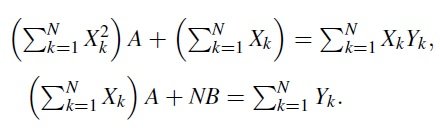

After A and B have been found, the parameter C in equation $y={\textrm{Ce}}^{\textrm{AX}}$ is computed:


$$C={\textrm{Ce}}^B$$


- (0.2 points) What applications do the least-squares have? 

Its applications vary for many work areas, since for the least-squares different conic sections such as circular or elliptical arcs can be used, in addition to making use of trigonometric functions such as sine and cosine, as well as being widely used to calculate trajectories. of objects that are under the influence of gravity and follow a parabolic path ignoring air resistance. In the same way, it can be used for regression analysis in statistics to calculate errors with respect to data from a population.

#### **3.2 Implementing **

- (1.0 point) Create a Matlab function called my_lsline_name_lastname() to construct the least-squares line $y=A_X +B$ that fits the N data points ($x_k$, $y_k$) with k ∈ {1, · · · N}. For instance

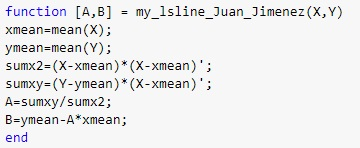

- (0.5 point) Use the created function to find the least-squares line $y=f\left(x\right)=$$A_X +B$ for the data and calculate $E_2 \left(f\right)$

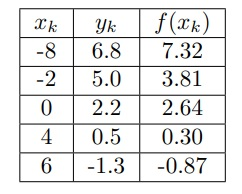

X=[-8,-2,0,4,6];
Y=[6.8,5.0,2.2,0.5,-1.3];
[a,b]=my_lsline_Juan_Jimenez(X,Y)

a = -0.5850

b = 2.6400

- (0.5 points) Plot the least-squares line and the given points from before item. Discuss what you observe.

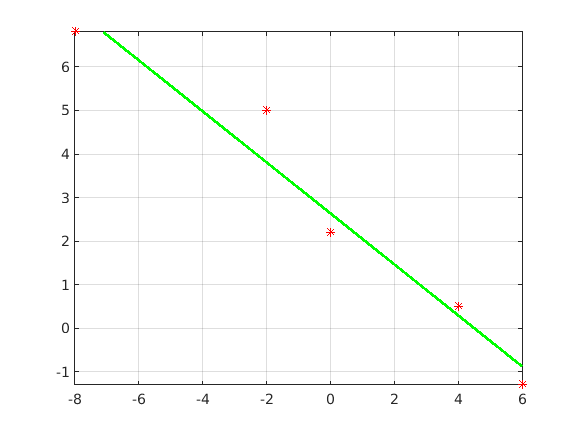

syms fun(x);
fun1a=a*x+b;
fun1b=@(x) a.*x+b;
fplot(fun1a,'LineWidth',2,'color','green'),xlim([min(X) max(X)]), ylim([min(Y) max(Y)]),
hold on,
plot(X,Y,'*','color','red'),
hold on,
grid on,

#### ANALYSIS of the 3.2 implementing:

For the following exercise we are asked to create a code that has the ability to construct the same squares for $y=A_X +B$ that fits the N data points in such a way that allows us to obtain the respective coefficients of both A and B in such a way that we can obtain an approximate curve which when graphing it shows the passage of this through the points or that is very next to these. It should be noted that the points are the calculation data. With the function [a,b]=my_lsline_Juan_Jimenez(X,Y) we are going to take X as the vector of the abscissa and Y as the vector of the ordinate, these values will be used since they will be the ones that take the values of the vectors and their respective positions. The function processes the input received and returns the values of A and also of B, it should be remembered that A is the coefficient of x in Ax + B and B is the constant coefficient in Ax + B. When obtaining these values, the line y = Ax + B can be formed and after this, the respective graph of the function can be created where we digitize the points and also program the line that will pass through or near them.

#### 3.3 Interpreting 

Kepler’s laws of planetary motion describe the motions of the planets in the solar system. Specifically, the third Kepler’s law establishes the square of the orbital period of a planet is directly proportional to the cube of the semi-major axis of its orbit. This law captures the relationship between the distance of planets from the Sun, and their orbital periods. Then

#### 

where T is the orbital period, R is the semi-major axis of its orbit, and C is the Kepler’s constant. Here, C is given by

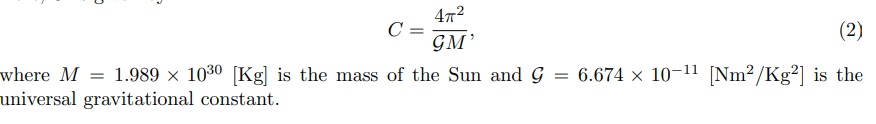

- (0.8 points) Use the created function to find the least-squares line $y=A_X +B$ for the planetary data, as shown in Table 1, considering

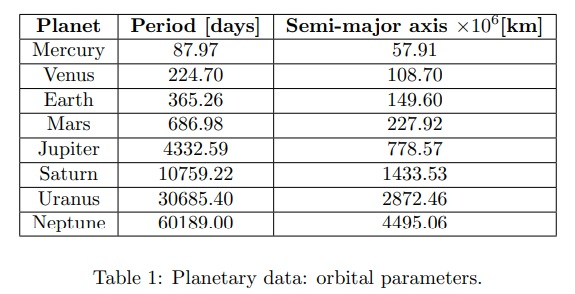

R = [57.91 108.70 149.60 227.92 778.57 1433.53 2872.46 4495.06].*10^9; 
T = [87.97 224.70 365.26 686.98 4332.59 10759.22 30685.40 60189]*86400;
n=size(R,2);
k=1:n;
X(k)=log10(R(k).^3);
Y(k)=log10(T(k).^2);
[a,b]=my_lsline_Juan_Jimenez(X,Y)

a = 1.0000

b = -18.5288

- (0.8 points) Construct a sketch similar to illustrate in Fig. 1 from the least-squares line computed previously. 

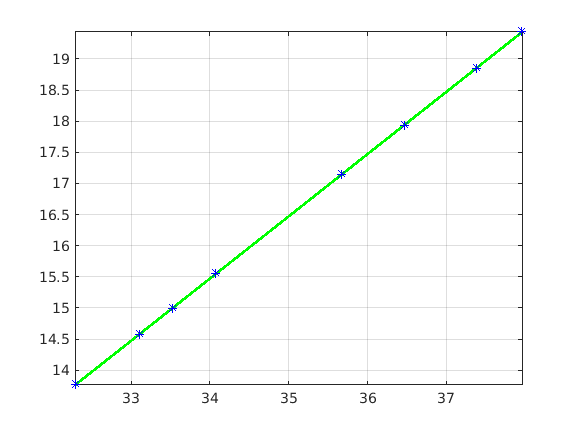

fun2=a*x+b;
fplot(fun2,'LineWidth',2,'color','green'),xlim([min(X) max(X)]), ylim([min(Y) max(Y)]),
hold on,
plot(X,Y,'*','color','blue'),
hold on
grid on

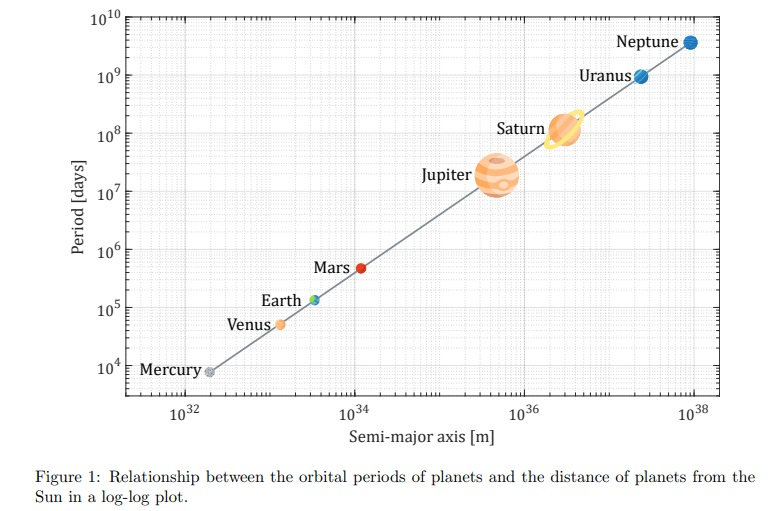

#### ANALYSIS of the 3.3 interpreting part 1:

For this initial ecuation: 

It must be taken into account according to the formula that T has been the period of the planet in days, C is the constant of proportionality, and that r is the average distance of the solo but in meters so the first thing we must do is pass the values that It shows us the table from kilometers to meters and the days to seconds. After that we have to decompose the function and the following will be to apply the logarithm in base10 to both sides of the equation

#### 
$$\log_{10} \left(T^2 \right)=\log_{10} \left(C*r^3 \right)$$


We multiply the logarithm in base 10 both to C and to r ^ 3 that is to say make use of the properties of the logarithms and we obtain as a result

#### 
$$\log_{10} \left(T^2 \right)={\log_{10} \left(r^3 \right)+\log }_{10} \left(C\right)$$


Well, so far everything is correct so having done the respective clearances we have a line of the form y = Ax + B

#### y = $\log_{10} \left(T^2 \right)$ ; x = $\log_{10} \left(r^3 \right)$ ; A = 1 ; B =$\log_{10} \left(C\right)$  

After this, we create the vectors and assign them their respective value for both R and T with their respective positions, and we also do the conversion and calculation of said values using the formula. After this we will obtain the values for A and B in such a way that the line y = Ax + B can be formed, and after this we will then create the function to be able to graph the line. From this we can see that the line passes over all the points, although the values of these may be closer than others.

- (0.6 points) Find an approximation of the universal gravitational constant G through the leastsquares line computed previously. Compare the estimated gravitational constant regarding the theoretical value using relative error. Hint. Use C = ${10}^B$ and formula (2). Be careful with the units. 

#### ANALYSIS of the 3.3 interpreting part 2:

disp('We define the value of each variable of the formula');

We define the value of each variable of the formula


Gteorico=6.674*10.^-11;
M=1.989*10.^30;
disp('We define the value of Cexperimental that arises from 10 ^ B = C');

We define the value of Cexperimental that arises from 10 ^ B = C


Cexperimental=10.^b

Cexperimental = 2.9593e-19

disp('We do the clearing in such a way that we pass C to multiply and G to divide');

We do the clearing in such a way that we pass C to multiply and G to divide


disp('Now we calculate the Gexperimental value');

Now we calculate the Gexperimental value


Gexperimental=(4*pi.^2)/(Cexperimental*M)

Gexperimental = 6.7071e-11

disp('Finally we determine the value of the relative error whose formula is ((Theoretical value - Experimental value) / Theoretical value)');

Finally we determine the value of the relative error whose formula is ((Theoretical value - Experimental value) / Theoretical value)


ErrorRelativo=abs((Gteorico-Gexperimental)/Gteorico);
disp('Relative Error:');

Relative Error:


disp(ErrorRelativo);

    0.0050



### ANEXES:

function [A,B] = my_lsline_Juan_Jimenez(X,Y)
xmean=mean(X);
ymean=mean(Y);
sumx2=(X-xmean)*(X-xmean)';
sumxy=(Y-ymean)*(X-xmean)';
A=sumxy/sumx2;
B=ymean-A*xmean;
end

### References:

- 하람, 유. (2020). Solutions Manual to accompany Applied Numerical Methods With MATLAB for Engineers and Scientists. Retrieved 26 November 2020, from [https://www.academia.edu/8589710/Solutions_Manual_to_accompany_Applied_Numerical_Methods_With_MATLAB_for_Engineers_and_Scientists](https://www.academia.edu/8589710/Solutions_Manual_to_accompany_Applied_Numerical_Methods_With_MATLAB_for_Engineers_and_Scientists)

- Curve fitting. (2021). Retrieved 11 February 2021, from [https://en.wikipedia.org/wiki/Curve_fitting](https://en.wikipedia.org/wiki/Curve_fitting)

- Molina, M. (2021). La distancia más corta. El método de los mínimos cuadrados. - AnestesiaR. Retrieved 11 February 2021, from [https://anestesiar.org/2020/la-distancia-mas-corta-el-metodo-de-los-minimos-cuadrados/](https://anestesiar.org/2020/la-distancia-mas-corta-el-metodo-de-los-minimos-cuadrados/)

- ▷El Método de mínimos cuadrados: definición y ejemplos☑ - MiProfe.com. (2021). Retrieved 11 February 2021, from [https://miprofe.com/minimos-cuadrados/](https://miprofe.com/minimos-cuadrados/)

- (2021). Retrieved 11 February 2021, from [https://cicese.repositorioinstitucional.mx/jspui/bitstream/1007/1904/1/40711.pdf](https://cicese.repositorioinstitucional.mx/jspui/bitstream/1007/1904/1/40711.pdf)

- Graphing: Linearization - AP Physics 1 Online. (2021). Retrieved 11 February 2021, from [https://sites.google.com/site/apphysics1online/appendices/2-data-analysis/graph-linearization](https://sites.google.com/site/apphysics1online/appendices/2-data-analysis/graph-linearization)